## Audio Import

[mus,Fs] = audioread('testf.wav');
mus1 = mus(1:end,1);

## **Audio Info**

audioinfo('testf.wav')

ans = struct with fields:
             Filename: '/Users/himanshu_pc/Documents/Work/Matlab/testf.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 2
           SampleRate: 44100
         TotalSamples: 2217600
             Duration: 50.2857
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


## **Fourier Transfor of original audio**

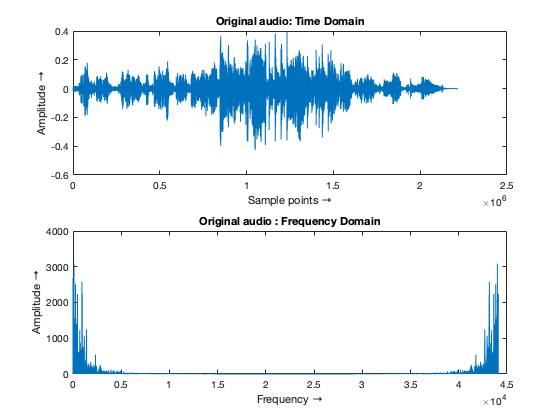

T = 1/Fs;
dt = 0 : T : (50.2857-T);
len = length(mus1);
len1 = 2^nextpow2(len);


xft = (Fs*(0:len1-1)/len1)';
ft = fft(mus1,len1);


figure("Name","A")
hold on
subplot(2,1,1);
plot(mus1);
title('Original audio: Time Domain'); 
xlabel('Sample points →');  ylabel('Amplitude →');

subplot(2,1,2);
plot(xft,abs(ft));
title('Original audio : Frequency Domain'); 
xlabel('Frequency →');  ylabel('Amplitude →');
hold off

## **Fourier Transform of extracted audio**

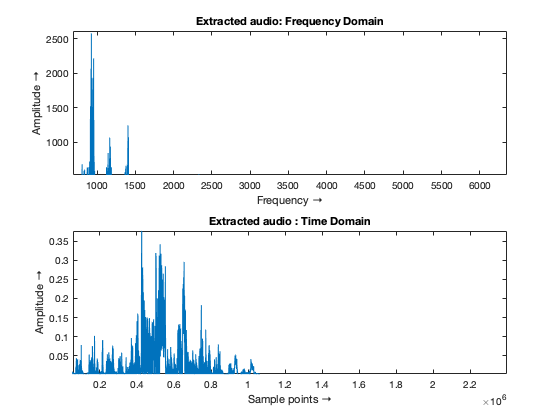

new1 = ft(1:length(ft)/2);
x_ft = xft(1:length(xft)/2);


%Voice  (800Hz - 3700Hz) Some peak range: (1100Hz - 1500Hz ; 2200Hz - 2400Hz ; 2700Hz - 2900Hz) 

new1(1:76080,1)        = 0;     % 76080 : 800Hz
new1(95100:104620,1)   = 0;      
new1(142660:209240,1)  = 0;
new1(350000:end,1)     = 0;      
new1(228260:256794,1)  = 0;
new1(350000:end,1)     = 0;     % 350000 : 3700Hz

inv1 = ifft(new1);
voice = (inv1 + conj(inv1))/2;


figure("Name","B")
hold on
subplot(2,1,1);
plot(x_ft,abs(new1))
title('Extracted audio: Frequency Domain'); 
xlabel('Frequency →');  ylabel('Amplitude →');

subplot(2,1,2);
plot(abs(inv1))
title('Extracted audio : Time Domain'); 
xlabel('Sample points →');  ylabel('Amplitude →');
hold off

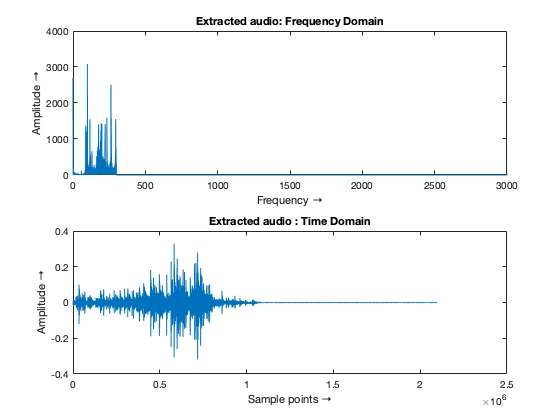

new2 = ft(1:length(ft)/2,1);

% guitar  (0 - 400Hz)

new2(28500:285320,1) = 0;  


inv2 = ifft(new2);
guit = (inv2 + conj(inv2))/2;

figure("Name","C")
hold on
subplot(2,1,1);
plot(x_ft,abs(new2)); xlim([0 3000]);
title('Extracted audio: Frequency Domain'); 
xlabel('Frequency →');  ylabel('Amplitude →');

subplot(2,1,2);
plot(guit); 
title('Extracted audio : Time Domain'); 
xlabel('Sample points →');  ylabel('Amplitude →');
hold off

audiowrite('voice.wav',voice,Fs/2);
audiowrite('guit.wav',guit,Fs/2);